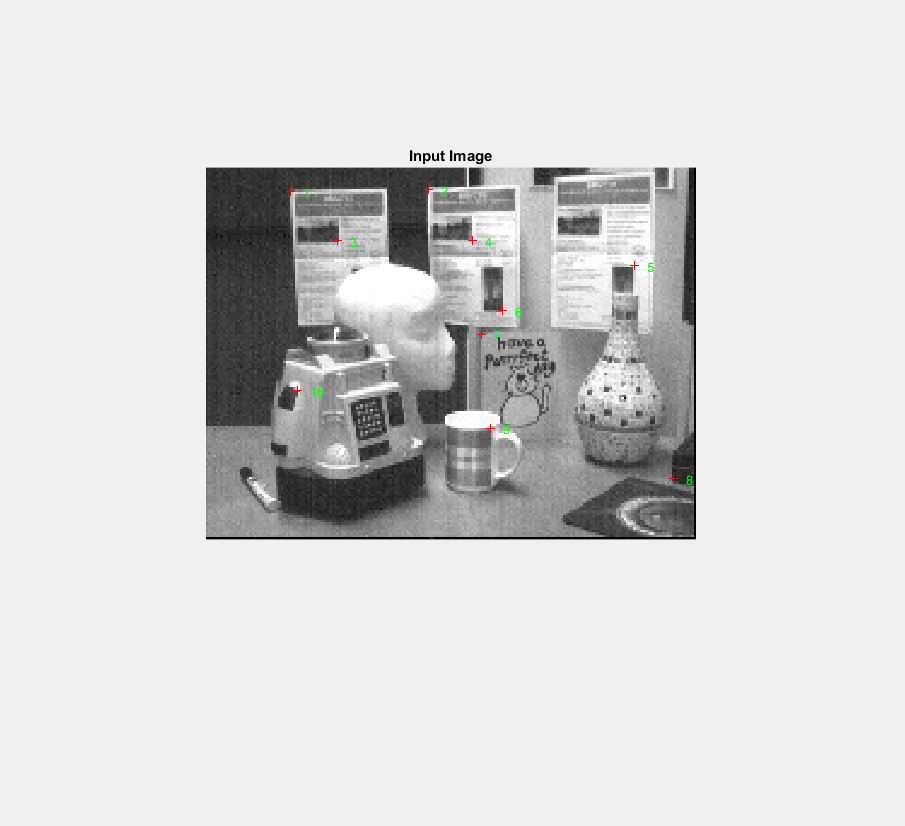

% Read in the input images
left = 'desk1.gif';
right = 'desk2.gif';
l = imread(left);
r = imread(right);

% Convert to double
l = double(l);
r = double(r);
% Pick the corresponding corners
xl = clickPoints(l, 10, 1, 1);

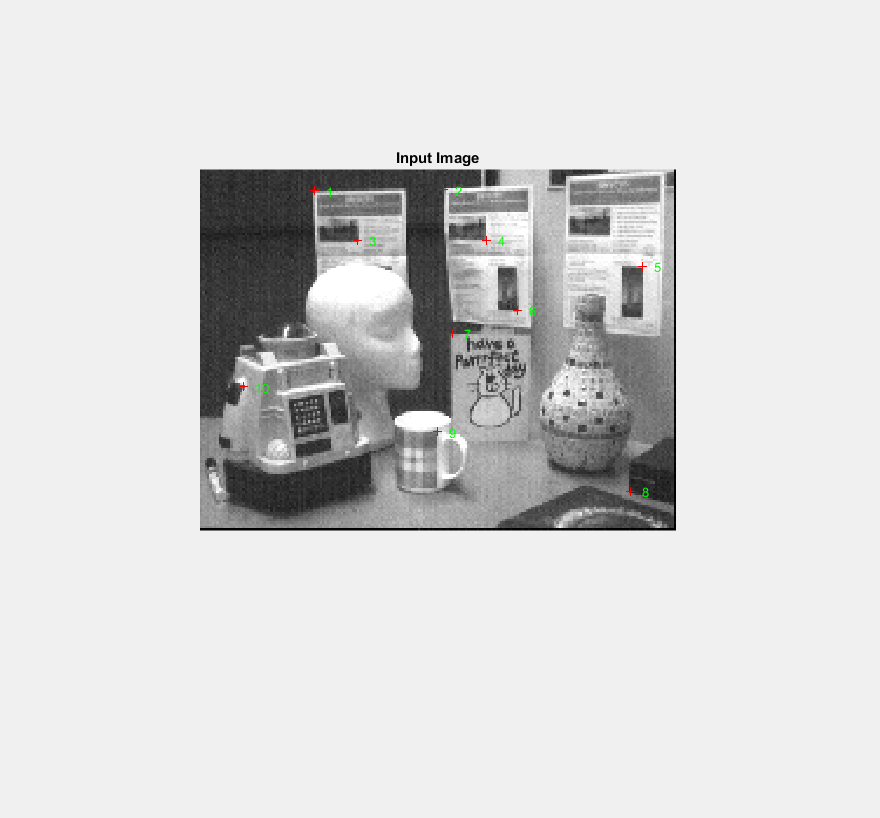

xr = clickPoints(r, 10, 1, 1);

xl = [xl; ones(size(xl(1,:)))];
xr = [xr; ones(size(xr(1,:)))];



a = [1 2 3;4 5 6];
%a(3,:) = ones(size(a,1),1);
a = [a; ones(size(a(1,:)))];
disp(a);

     1     2     3
     4     5     6
     1     1     1



% Compute the fundamental matrix
F = computeF(xr, xl);

   1.0e+04 *

    0.5883    0.6459    0.0076    0.4394    0.4824    0.0057    0.0077    0.0085    0.0001
    0.4480    1.2372    0.0078    0.9176    2.5340    0.0161    0.0057    0.0158    0.0001
    2.9974    2.0217    0.0157    1.3500    0.9106    0.0071    0.0191    0.0129    0.0001
    2.5317    3.1247    0.0157    2.8211    3.4818    0.0175    0.0161    0.0199    0.0001
    4.3571    0.7690    0.0191    0.9537    0.1683    0.0042    0.0228    0.0040    0.0001
    4.7334    2.5149    0.0196    1.7069    0.9069    0.0071    0.0241    0.0128    0.0001
    0.2051    1.3643    0.0066    0.6459    4.2978    0.0208    0.0031    0.0207    0.0001
    0.0968    1.3372    0.0069    0.3555    4.9114    0.0255    0.0014    0.0193    0.0001
    0.8469    2.8873    0.0105    2.0807    7.0936    0.0257    0.0081    0.0276    0.0001
    3.1857    4.9489    0.0181    4.4977    6.9872    0.0255    0.0176    0.0273    0.0001



disp(F);

    0.0000    0.0000   -0.0457
    0.0000   -0.0000    0.0131
    0.0298   -0.0086    0.9984



disp(xl(:,9)'*F*xr(:,9));

   -0.2371



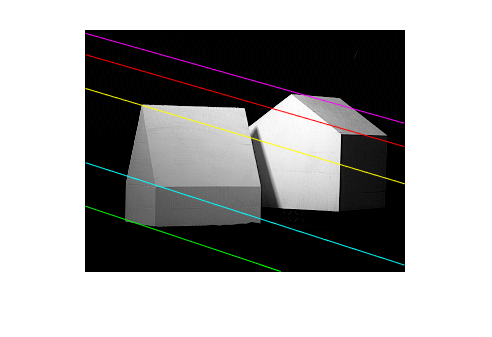

% Compute the epipolar lines in the left image
leftlines = F*xr;
% Compute the epipolar lines in the right image
rightlines = F'*xl;
% Draw epipolar lines on the left image
figure; imshow(l,[]); axis image; hold on;
drawLine(leftlines(:,1), l, 'yellow');
drawLine(leftlines(:,3), l, 'cyan');
drawLine(leftlines(:,5), l, 'green');
drawLine(leftlines(:,7), l, 'magenta');
drawLine(leftlines(:,9), l, 'red');
hold off;

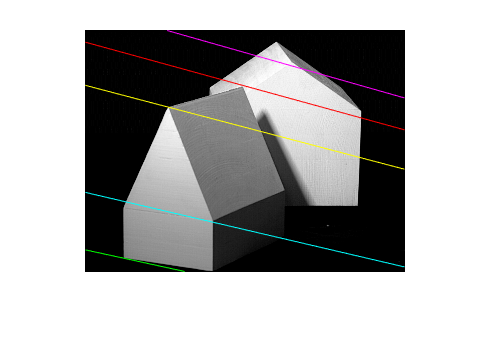

% Draw epipolar lines on the right image
figure; imshow(r,[]); axis image; hold on;
drawLine(rightlines(:,1), r, 'yellow');
drawLine(rightlines(:,3), r, 'cyan');
drawLine(rightlines(:,5), r, 'green');
drawLine(rightlines(:,7), r, 'magenta');
drawLine(rightlines(:,9), r, 'red');
hold off;

% epipole
disp(null(F));

    0.2679
    0.9635
    0.0003




elh = null(F)

elh =     0.2679
    0.9635
    0.0003


el = [elh(1,1)/elh(3,1)  elh(2,1)/elh(3,1)]

el =    1.0e+03 *

    1.0176    3.6600


disp(el);

   1.0e+03 *

    1.0176    3.6600




disp(null(F'));

   -0.2704
   -0.9627
    0.0003



erh = null(F')

erh =    -0.2704
   -0.9627
    0.0003


er = [erh(1,1)/erh(3,1)  erh(2,1)/erh(3,1)]

er =    1.0e+03 *

   -0.9289   -3.3067


disp(er);

   1.0e+03 *

   -0.9289   -3.3067



function [F] = computeF(xl, xr)
%A = zeros(10,9);
%for i = 1:10
%    u = xl(1,i);
%    v = xl(2,i);
%    up = xr(1,i);
%    vp = xr(2,i);
%    A(i,:) = [u*up v*up up u*vp v*vp vp u v 1];
%end

A=[xr(1,:)'.*xl(1,:)'	xr(1,:)'.*xl(2,:)' xr(1,:)' ...
xr(2,:)'.*xl(1,:)' xr(2,:)'.*xl(2,:)' xr(2,:)'	...
xl(1,:)' xl(2,:)' ones(10,1)	];
disp(A);
[U,D,V] = svd(A);
F = reshape(V(:,9),3,3)';
[U,D,V] = svd(F);
F = U*diag([D(1,1) D(2,2) 0])*V';
end
